% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Train / Test Baseline Models **********

% 1a) Baseline Decision Tree
disp('***** Baseline Decision Tree *****')

***** Baseline Decision Tree *****


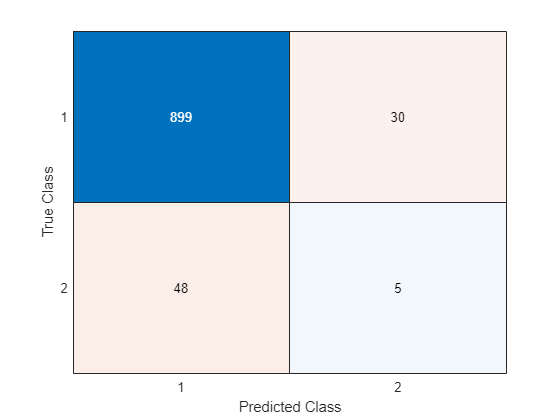

accuracy = 0.9206

precision = 0.1429

recall = 0.0943

specificity = 0.9677

fb = 0.1136

% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

% 1b) Baseline KNN
disp('***** Baseline KNN *****')

***** Baseline KNN *****


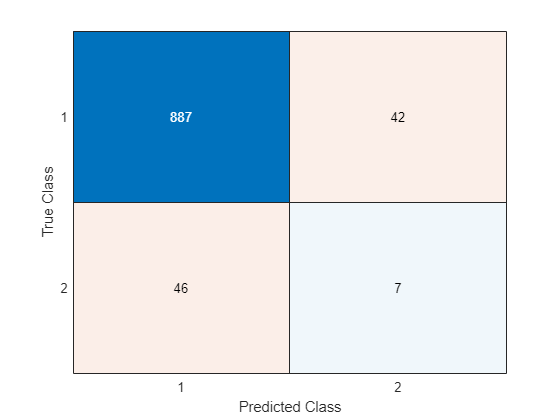

accuracy = 0.9104

precision = 0.1429

recall = 0.1321

specificity = 0.9548

fb = 0.1373

% Train
knn_base = fitcknn(X_train, y_train);
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

% ********** 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy) **********

rng(1) % for reproducability

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
prune = optimizableVariable('prune', {'on','off'},'Type','categorical'); % default: 'on'
PruneCriterion = optimizableVariable('PruneCriterion',  {'error', 'impurity'}, 'Type','categorical'); % default: 'error'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1

ParamsDT = [prior, prune, PruneCriterion, MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'chebychev','cityblock', 'euclidean','minkowski'},'Type','categorical'); % default: euclidean
dstWeight = optimizableVariable('dstWeight', {'equal','inverse', 'squaredinverse'},'Type','categorical');  % default: equal
NSMethod = optimizableVariable('NSMethod', {'kdtree','exhaustive'},'Type','categorical');  % default: exhaustive
BucketSize = optimizableVariable('BucketSize',[1,100],'Type','integer');  % defualt: 50

ParamsKNN = [prior; n; dst; dstWeight; NSMethod; BucketSize];

% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
disp('***** Hyperparameter Tuning Decision Tree (CV = k-fold, loss = accuracy) *****')

***** Hyperparameter Tuning Decision Tree (CV = k-fold, loss = accuracy) *****


|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |        prune | PruneCriteri-|  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |
|==================================================================================================================================================|
|    1 | Best   |     0.26649 |     0.13879 |     0.26649 |     0.26649 |      uniform |           on |     impurity |           14 |            4 |
|    2 | Accept |     0.28437 |     0.14584 |     0.26649 |     0.27243 |      uniform |           on |        error |           27 |           16 |
|    3 | Accept |     0.26969 |     0.11456 |     0.26649 |      0.2665 |      uniform |           on |   

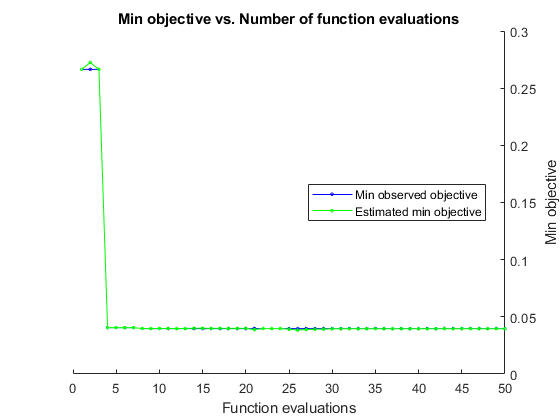


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 19.7901 seconds
Total objective function evaluation time: 6.33

Best observed feasible point:
      prior      prune    PruneCriterion    MaxNumSplit    MinLeafSize
    _________    _____    ______________    ___________    ___________

    empirical     off        impurity            3              2     

Observed objective function value = 0.039735
Estimated objective function value = 0.040179
Function evaluation time = 0.11376

Best estimated feasible point (according to models):
      prior      prune    PruneCriterion    MaxNumSplit    MinLeafSize
    


% i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, ...
                                     'prior', char(params.prior), ...
                                     'prune', char(params.prune), ...
                                     'PruneCriterion', char(params.PruneCriterion), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));
% ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

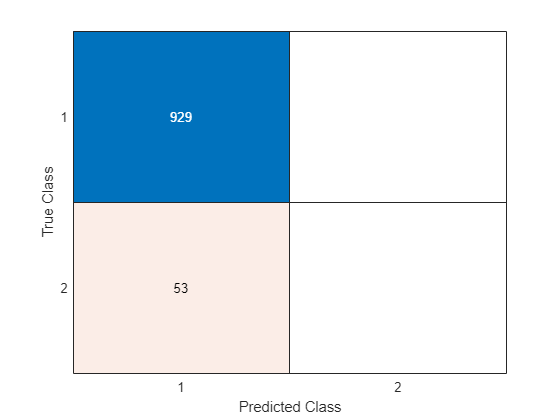

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

fb = 0


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, ...
    'prior', char(z.prior), ...
    'prune', char(z.prune), ...
    'PruneCriterion', char(z.PruneCriterion), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
disp('***** Hyperparameter Tuning KNN  (CV = k-fold, loss = accuracy) *****')

***** Hyperparameter Tuning KNN  (CV = k-fold, loss = accuracy) *****


|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |     NSMethod |   BucketSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |
|=================================================================================================================================================================|
|    1 | Best   |    0.068518 |     0.16457 |    0.068518 |    0.068518 |    empirical |            1 |    cityblock |        equal |   exhaustive |           84 |
|    2 | Accept |     0.31061 |     0.16468 |    0.068518 |    0.078143 |      uniform |           14 |    chebychev | squaredinver |   exhaustive |           72 |
|    3 | Best   

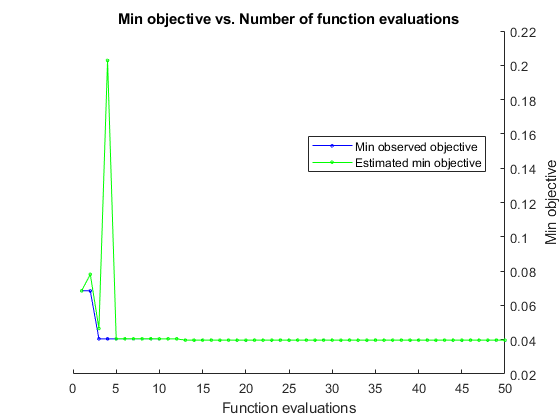


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 26.5053 seconds
Total objective function evaluation time: 10.9262

Best observed feasible point:
      prior      n        dst       dstWeight     NSMethod     BucketSize
    _________    __    _________    _________    __________    __________

    empirical    20    euclidean      equal      exhaustive        28    

Observed objective function value = 0.039735
Estimated objective function value = 0.03975
Function evaluation time = 0.19066

Best estimated feasible point (according to models):
      prior      n        dst       dstWeight     


% i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'CVPartition', c, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight), ...
            'NSMethod', char(params.NSMethod), ...
            'BucketSize', params.BucketSize));

% ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

fb = 0


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight), ...
    'NSMethod', char(z.NSMethod), ...
    'BucketSize', z.BucketSize);

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta) **********

% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
disp('***** Hyperparameter Tuning Decision Tree (CV = k-fold, loss = f-beta) *****')

***** Hyperparameter Tuning Decision Tree (CV = k-fold, loss = f-beta) *****



% i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c) % see helper function

loss = function_handle with value:
    @(params)fb_loss_dt_cv(params,X_train,y_train,c)


|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |        prune | PruneCriteri-|  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |
|==================================================================================================================================================|
|    1 | Best   |           1 |     0.11967 |           1 |           1 |    empirical |          off |        error |            2 |           27 |
|    2 | Best   |     0.95531 |     0.14913 |     0.95531 |     0.95757 |    empirical |          off |        error |           28 |            7 |
|    3 | Accept |           1 |     0.16418 |     0.95531 |     0.95535 |    empirical |           on |   

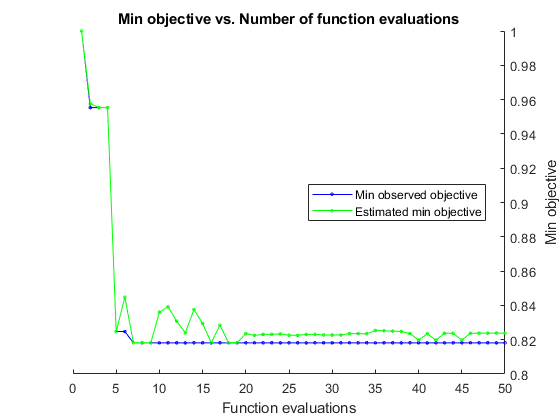


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 20.0702 seconds
Total objective function evaluation time: 6.8963

Best observed feasible point:
     prior     prune    PruneCriterion    MaxNumSplit    MinLeafSize
    _______    _____    ______________    ___________    ___________

    uniform     on         impurity           11             25     

Observed objective function value = 0.81818
Estimated objective function value = 0.83167
Function evaluation time = 0.11864

Best estimated feasible point (according to models):
     prior     prune    PruneCriterion    MaxNumSplit    MinLeafSize
    _______


% ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

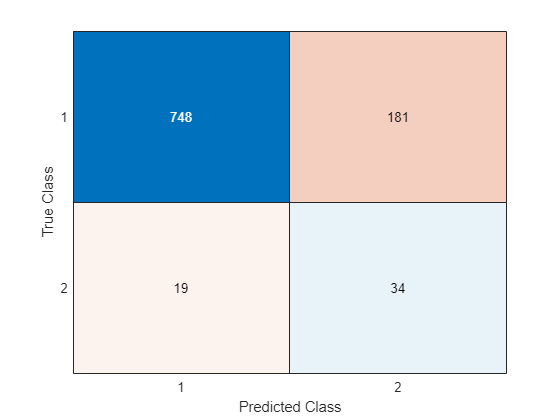

accuracy = 0.7963

precision = 0.1581

recall = 0.6415

specificity = 0.8052

fb = 0.2537


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, ...
    'prior', char(z.prior), ...
    'prune', char(z.prune), ...
    'PruneCriterion', char(z.PruneCriterion), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = k-fold, loss = f-beta) *****')

***** Hyperparameter Tuning KNN (CV = k-fold, loss = f-beta) *****



% i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c) % see helper function

loss = function_handle with value:
    @(params)fb_loss_knn_cv(params,X_train,y_train,c)


|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |     NSMethod |   BucketSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.83156 |      0.1707 |     0.83156 |     0.83156 |      uniform |           11 |    cityblock |        equal |   exhaustive |           80 |
|    2 | Accept |     0.83591 |     0.23609 |     0.83156 |     0.83203 |      uniform |           14 |    euclidean | squaredinver |       kdtree |           91 |
|    3 | Accept 

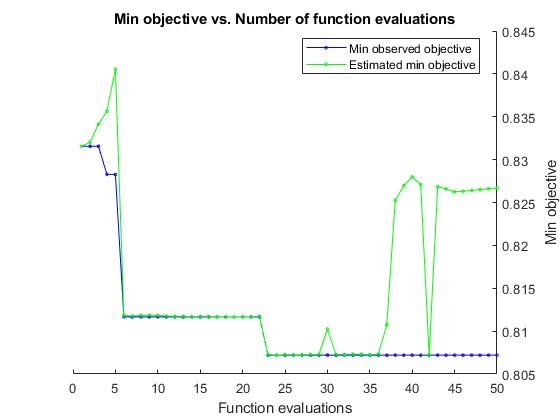


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 26.0528 seconds
Total objective function evaluation time: 10.0303

Best observed feasible point:
     prior     n       dst       dstWeight     NSMethod     BucketSize
    _______    _    _________    _________    __________    __________

    uniform    6    minkowski      equal      exhaustive        36    

Observed objective function value = 0.8072
Estimated objective function value = 0.83414
Function evaluation time = 0.19254

Best estimated feasible point (according to models):
     prior     n       dst         dstWeight        NSMet


% ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

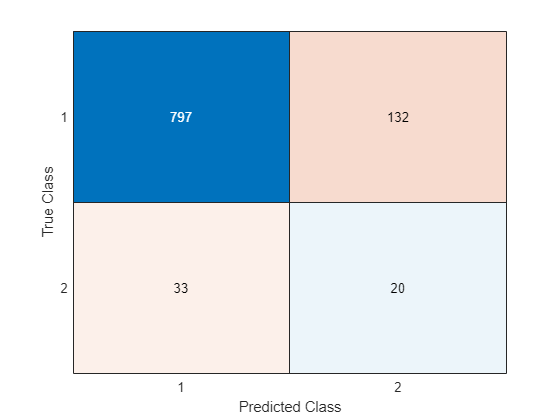

accuracy = 0.8320

precision = 0.1316

recall = 0.3774

specificity = 0.8579

fb = 0.1951


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight), ...
    'NSMethod', char(z.NSMethod), ...
    'BucketSize', z.BucketSize);

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta) **********

% CV SPLITS (Stratified)
c = cvpartition(y_train,'KFold', 20, 'Stratify', true);

% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning Decision Tree (CV = statify, loss = f-beta) *****')

***** Hyperparameter Tuning Decision Tree (CV = statify, loss = f-beta) *****



% i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c) % see helper function

loss = function_handle with value:
    @(params)fb_loss_dt_cv(params,X_train,y_train,c)


|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |        prune | PruneCriteri-|  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |
|==================================================================================================================================================|
|    1 | Best   |     0.95604 |     0.14774 |     0.95604 |     0.95604 |    empirical |          off |        error |           29 |           17 |
|    2 | Accept |           1 |     0.13233 |     0.95604 |     0.97513 |    empirical |           on |        error |           18 |           29 |
|    3 | Accept |           1 |     0.13895 |     0.95604 |     0.95612 |    empirical |           on |   

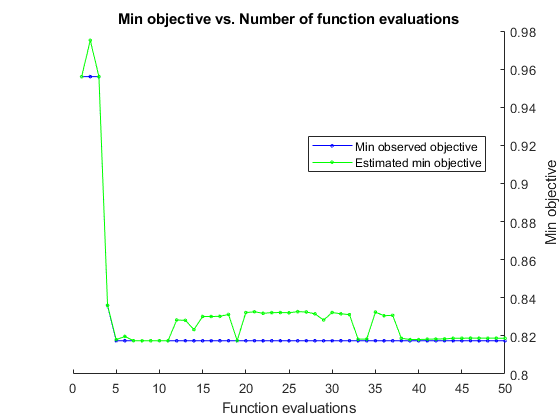


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 21.857 seconds
Total objective function evaluation time: 7.0595

Best observed feasible point:
     prior     prune    PruneCriterion    MaxNumSplit    MinLeafSize
    _______    _____    ______________    ___________    ___________

    uniform     on         impurity           10             28     

Observed objective function value = 0.81745
Estimated objective function value = 0.81928
Function evaluation time = 0.14946

Best estimated feasible point (according to models):
     prior     prune    PruneCriterion    MaxNumSplit    MinLeafSize
    _______<


% ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

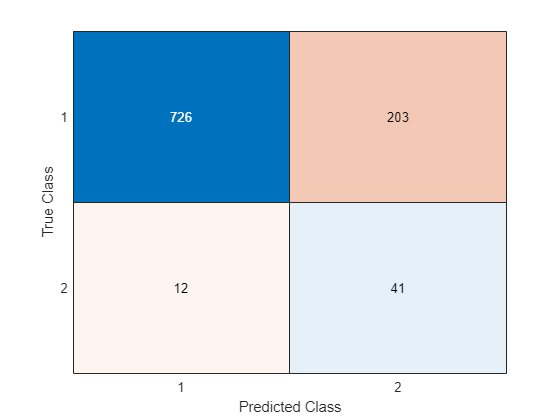

accuracy = 0.7811

precision = 0.1680

recall = 0.7736

specificity = 0.7815

fb = 0.2761


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, ...
    'prior', char(z.prior), ...
    'prune', char(z.prune), ...
    'PruneCriterion', char(z.PruneCriterion), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****')

***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****



% i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c) % see helper function

loss = function_handle with value:
    @(params)fb_loss_knn_cv(params,X_train,y_train,c)


|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |     NSMethod |   BucketSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.83064 |     0.18027 |     0.83064 |     0.83064 |      uniform |           15 |    minkowski | squaredinver |   exhaustive |           59 |
|    2 | Accept |     0.87205 |     0.13535 |     0.83064 |     0.83229 |    empirical |            1 |    euclidean |        equal |   exhaustive |           57 |
|    3 | Accept 

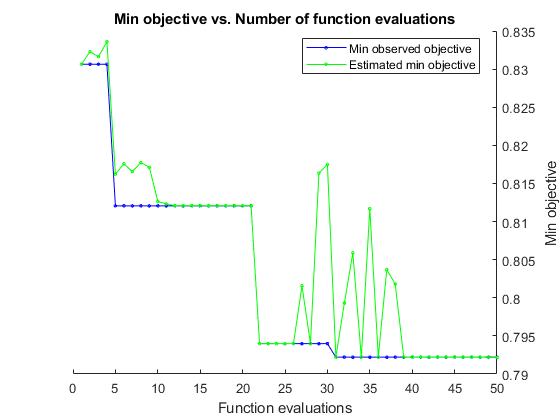


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 25.9671 seconds
Total objective function evaluation time: 11.6995

Best observed feasible point:
     prior     n       dst         dstWeight       NSMethod    BucketSize
    _______    _    _________    ______________    ________    __________

    uniform    5    chebychev    squaredinverse     kdtree         81    

Observed objective function value = 0.79221
Estimated objective function value = 0.79223
Function evaluation time = 0.18606

Best estimated feasible point (according to models):
     prior     n       dst       dstWeight    N


% ii) Optimize model
results = bayesopt(@(params)fb_loss_knn_cv(params,X_train,y_train, c), ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

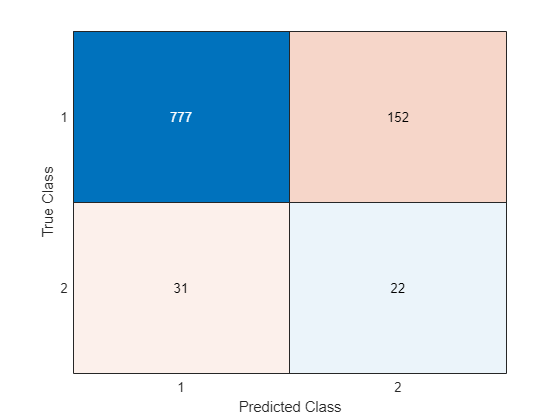

accuracy = 0.8136

precision = 0.1264

recall = 0.4151

specificity = 0.8364

fb = 0.1938


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight), ...
    'NSMethod', char(z.NSMethod), ...
    'BucketSize', z.BucketSize);

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, ...
             'prior', char(params.prior), ...
             'prune', char(params.prune), ...
             'PruneCriterion', char(params.PruneCriterion), ...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight), ...
            'NSMethod', char(params.NSMethod), ...
            'BucketSize', params.BucketSize);
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 